# Sea Water Reverse Osmosis

This livescript covers how to use some of the advanced features of this toolbox in sea water reverse osmosis (SWRO) modeling. The features covered are polarization, variable membrane transport parameters, multiple solutes, and scaling/fouling.

## Basic Model

First we will look at a basic model that does not include any of these advanced features to see the base line model results. You'll notice that the architecture of this system is a little different from the optimization example. These changes are to make it easier for the solver as well as minic a real system. The pressure ramps up slowly over the first minute and instead of initializing the feed stream with seawater, it begins with pure water in the feed stream, sourced from a constant volume chamber which gets filled with seawater over the course of the pressure ramp process, therefore, we see a smooth transition from steady statee into desalination with both concentration and pressure ramping up to target feed states. This significantly improves the performance of the model, particuyalry when we add some of the advanced features, notably scaling.

open('SWRO.slx')
ResetParams();
set_params_700psi;
set_param('SWRO/Membrane','coefficient_type','1') % Constant
set_param('SWRO/Membrane','A_w','0.104')
set_param('SWRO/Membrane','A_w_unit','l/(m^2*hr*psi)')
set_param('SWRO/Membrane','B_s','0.108')
set_param('SWRO/Membrane','B_s_unit','l/(m^2*hr)')
set_param('SWRO/Membrane','polarization_type','1') % None
out = sim('SWRO');
basic_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
basic_900 = out.simlog;
set_params_500psi
out = sim('SWRO');
basic_500 = out.simlog;

cases = {basic_500, basic_700, basic_900};
results = calc_ro_metrics(cases,1800);
results.Applied_Pressure = [500; 700; 900];
BasicResultsTable = ResultsTable(results);
disp(BasicResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.7               4.2            4.4               99.9                        969                    40.3  
             700                    20.7              21.5           12.8               99.9                        205                   206.5  
             900                    33.3              41.3           15.3                100                        108                   397.3  



We ran the basic desalination model at 3 different pressures for 9 minutes after ramping up over 60 seconds. We can see some expected behaviors. As applied pressure increases, feed flow, flux, recovery ratio, and salt rejection all increase while permeate concentration decreases. We also see net driving pressure (NDP) increase. NDP is the difference between the hydraulic pressure difference and the osmotic pressure difference accross the membreane. However, we can do better. One way we can improve upon this model is through adding polarization.

## Polarization

Polarization is the effect where the fluid near the membrane has a higher concentration than the bulk flow, increasing the osmotic pressure difference and therefore reducing the NDP, flux, etc. This occus because as water flows through the membrane, it leaves the salt it was carrying right at the membrene surface which must then diffuse back into the bulk. We have included two ways of modeling polarization in the membrane block. The first and "more proper" way is to actually model this through diffusion. 

### Diffusion

In static flow, our diffusion equation for mass flow of solute $x$ ($\dot{M_x }$) is


$$$\dot{M}_x = D_x\frac{\Delta c}{\ell}A$$$


where $D_x$ is the diffusivity of our mixture, $\Delta c$ is the concentration difference, $\ell$ is the length scale that concentration difference is streatched over, and $A$ is the cross sectional area. Diffusion is actually present in the connections between many Simscape fluids blocks, however, the impact if quite small and so tuning $A$ and $\ell$ seperately is not important. In this domain, diffusion can be really important, therefore everyblock with volume has the option to set custom port lengths, which should be set to $\frac{\ell}{2}$ on both sides of the connection. Let's load an example.

open('diffusion_example.slx')

This example roughly represents a 2 liter bottle where initially, the bottom half of the bottle is full of a high concentration salt water and the top half has pure freshwater. Let's see what happens when we run the simulation for 250 days.

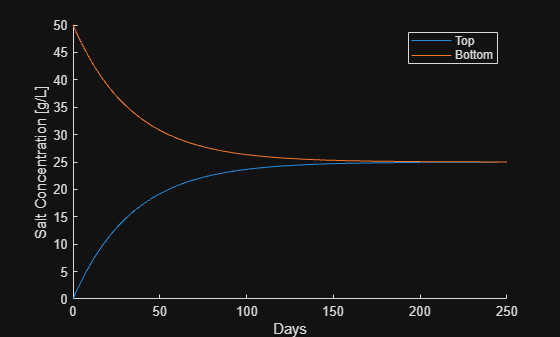

out = sim('diffusion_example');
t_diff = out.simlog.Bottom.x_I.series.time();
x_btm = out.simlog.Bottom.x_I.series.values('g/l');
x_top = out.simlog.Top.x_I.series.values('g/l');
figure('name','Diffusion Example')
line(t_diff/(60*60*24),x_top,'DisplayName','Top')
line(t_diff/(60*60*24),x_btm,'DisplayName','Bottom')
xlabel('Days')
ylabel('Salt Concentration [g/L]')
legend('Location','Best')

It's very important to note the time scale for this, 250 days. It is highly likely the 2-liter will be disturbed in some way, shaken, moved, etc. and will therfore mix much faster. As we can see, bulk motion of flow is going to dominate most mass transfer, unless we have very small volumes and very small diffusion length scales. In membrane polarization, we do.

In our membrane, we can model this diffusion polarization by creating a very small volume chamber that interacts with the membrane instead of the bulk volume. Let's add this to our basic SWRO model

### Diffusion in SWRO

open('SWRO.slx')
set_param('SWRO/Membrane','polarization_type','2') % Discrete Boundary Layer Volume
set_param('SWRO/Membrane','boundary_height','0.07')
set_param('SWRO/Membrane','boundary_height_unit','mm')
set_params_500psi;
out = sim('SWRO');
boundary_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
boundary_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
boundary_900 = out.simlog;
cases = {boundary_500, boundary_700, boundary_900};

results = calc_ro_metrics(cases,1800);

Applied_Pressure = [500; 700; 900];

BoundaryResultsTable = table( ...
    Applied_Pressure, ...
    round(results.Feed_Flow(:),1), ...
    round(results.Flux(:),1), ...
    round(results.Recovery(:)*100,1), ...
    round(results.Salt_Rejection(:)*100,1), ...
    round(results.Perm_Conc(:),0), ...
    round(results.Mean_NDP,1), ...
    'VariableNames', { ...
        'Applied Pressure [psi]', ...
        'Feed Flow [L/min]', ...
        'Flux [LMH]', ...
        'Recovery [%]', ...
        'Salt Rejection [%]', ...
        'Permeate Concentration [mg/L]', ...
        'NDP [psi]' ...
    });
disp(BoundaryResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.6               3.5            3.7               99.9                       1176                    33.5  
             700                    20.1              16.2            9.9               99.9                        299                   155.9  
             900                    31.9              30.1           11.6               99.9                        181                   289.4  



As we can see, this reduced the performance as predicted. The challenge with this strategy is setting that "boundary layer height" parameter. Unfortunately this is not a very practical parameter to use. Hard to measure and not reported in any membrane spec sheets. A more practical (but less "proper") way of quantifying polarization is through an exponential modifier on the concentration. 

### Exponential Modifier

The exponential modifier adjusts the concentration measurment ($$c_m$$) in a pipe based on the flow velocity and mass transfer of both solute and solvent. 


$$c_m = c \exp \left( \frac{J_{eff}}{k}\right)$$


where $c$ is the bulk concentration in the pipe, $J_{eff}$ is the effective solvent flux (more on this to come, for now just understand it as solvent flux), and $k$ is calculated as:


$$$$k = \frac{ShD_{x}}{d_h}$$$$


where $Sh$ is the Sherwood number, $D_{x}$ is the diffusivity of the solute (a fluid property), and $d_h$ is the hydraulic diameter of the feed side channel. The Sherwood number can be calculated through the following:


$$Sh = 0.14Re^{0.64}Sc^{0.42}$$



$$Re = \frac{vd_{h}}{\nu}$$



$$Sc = \frac{\nu}{D_{NaCl}}$$


where $v$ is the flow velocity and $\nu$ is the kinematic viscosity which we have access to through fluid properties.

Let's see how this compares.

open('SWRO.slx')
set_param('SWRO/Membrane','polarization_type','3') % Exponential Modifier
set_params_500psi;
out = sim('SWRO');
expmod_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
expmod_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
expmod_900 = out.simlog;
cases = {expmod_500,expmod_700,expmod_900};
results = calc_ro_metrics(cases,1800);
Applied_Pressure = [500; 700; 900];

ExpModResultsTable = table( ...
    Applied_Pressure, ...
    round(results.Feed_Flow(:),1), ...
    round(results.Flux(:),1), ...
    round(results.Recovery(:)*100,1), ...
    round(results.Salt_Rejection(:)*100,1), ...
    round(results.Perm_Conc(:),0), ...
    round(results.Mean_NDP,1), ...
    'VariableNames', { ...
        'Applied Pressure [psi]', ...
        'Feed Flow [L/min]', ...
        'Flux [LMH]', ...
        'Recovery [%]', ...
        'Salt Rejection [%]', ...
        'Permeate Concentration [mg/L]', ...
        'NDP [psi]' ...
    });
disp(ExpModResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.4               2.4           2.6                99.9                       1660                    23.3  
             700                    19.5              11.2           7.1                99.9                        472                   107.6  
             900                      31              22.9           9.1                99.9                        265                   219.9  



Once again this demonstrates a similar trend, but is easier to work with than the discete boundary volume strategy.

## Variable Transport Parameters

Water and salt permeability in SWRO membranes are not constant under all flow conditions, different NDPs can lead to different permeabilities. While constant permeabilities are perfectly fine in situations where the membrane is always operated under constant conditions, variable feed pressures/compositions and simulating under different operating conditions require variable transport parameters.

For ease of use our membrane block has the option to use a look-up table instead of these constant parameters, indexed by NDP.

open('SWRO.slx')
set_param('SWRO/Membrane','coefficient_type','2') % Variable - Look-up table
set_param('SWRO/Membrane','A_table','[0.121,0.109,0.104,0.100,0.099]')
set_param('SWRO/Membrane','A_table_unit','l/(m^2*hr*psi)')
set_param('SWRO/Membrane','B_table','[0.090,0.102,0.108,0.116,0.119]')
set_param('SWRO/Membrane','B_table_unit','l/(m^2*hr)')
set_param('SWRO/Membrane','B_table_y','[0,0,0,0,0]')
set_param('SWRO/Membrane','B_table_y_unit','l/(m^2*hr)')
set_param('SWRO/Membrane','NDP_index','[39.2,107.3,182.7,259.3,332.7]')
set_param('SWRO/Membrane','NDP_index_unit','psi')
set_params_500psi;
out = sim('SWRO');
vtp_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
vtp_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
vtp_900 = out.simlog;
cases = {vtp_500,vtp_700,vtp_900};
results = calc_ro_metrics(cases,1800);
Applied_Pressure = [500; 700; 900];

VTPResultsTable = table( ...
    Applied_Pressure, ...
    round(results.Feed_Flow(:),1), ...
    round(results.Flux(:),1), ...
    round(results.Recovery(:)*100,1), ...
    round(results.Salt_Rejection(:)*100,1), ...
    round(results.Perm_Conc(:),0), ...
    round(results.Mean_NDP,1), ...
    'VariableNames', { ...
        'Applied Pressure [psi]', ...
        'Feed Flow [L/min]', ...
        'Flux [LMH]', ...
        'Recovery [%]', ...
        'Salt Rejection [%]', ...
        'Permeate Concentration [mg/L]', ...
        'NDP [psi]' ...
    });
disp(VTPResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.4               2.4           2.6                99.9                       1397                    19.9  
             700                    19.5              11.4           7.2                99.9                        437                     104  
             900                      31              22.7             9                99.9                        277                   222.5  



What we notice is that while this doen't impact the flux all that much, it has a pretty significant impact on the permeate concentration. So in applications where peremeate concentration is important, this could be an imporant feature to leverage (and it doesn't slow the simulation down at all).

## Multiple Solutes

Up till now we've treated NaCl as one solute with an ion count ($i$) of 2, another way of representing this though is with 2 solutes, Na+ and Cl-, each with and ion count of 1. Using the second solute feature, we can do this, using the following changes. First, each solute is given an ion count of 1.

set_param('SWRO/Solution Settings (SS)','i','1');   % Na+
set_param('SWRO/Solution Settings (SS)','i_y','1'); % Cl-

Next, we will split the molar mass of 58.44 g/mol up between the two soultes.

set_param('SWRO/Solution Settings (SS)','M','22.99');   % Na+
set_param('SWRO/Solution Settings (SS)','M_y','35.45'); % Cl-

Similarly we will split the concentration up in the feed stream by the same ratio, representing the assumption that we have the same number of Na+ and Cl- ions.

set_param('SWRO/Feed','reservoir_concentration','14.87');   % Na+
set_param('SWRO/Feed','reservoir_concentration_y','22.93'); % Cl-
set_param('SWRO/Membrane','x0_feed','14.87');               % Na+
set_param('SWRO/Membrane','y0_feed','22.93');               % Cl-

For now, I'll set the densities the same, since it is only important to the scaling blocks we are not using yet

set_param('SWRO/Solution Settings (SS)','rho_species_y','2.17');

I will also keep diffusivity and membrane transport parameters the same and go back to the basic model, so we can validate easily.

set_param('SWRO/Solution Settings (SS)','D_y','1.32e-3');
set_param('SWRO/Membrane','coefficient_type','1') % Constant
set_param('SWRO/Membrane','A_w','0.104')
set_param('SWRO/Membrane','A_w_unit','l/(m^2*hr*psi)')
set_param('SWRO/Membrane','B_s','0.108')
set_param('SWRO/Membrane','B_s_y','0.108')
set_param('SWRO/Membrane','B_s_unit','l/(m^2*hr)')
set_param('SWRO/Membrane','B_s_y_unit','l/(m^2*hr)')
set_param('SWRO/Membrane','polarization_type','1') % None
set_params_700psi
out = sim('SWRO');
splitnacl_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
splitnacl_900 = out.simlog;
set_params_500psi
out = sim('SWRO');
splitnacl_500 = out.simlog;
cases = {splitnacl_500, splitnacl_700, splitnacl_900};
results = calc_ro_metrics(cases,1800);
results.Applied_Pressure = [500; 700; 900];
SplitNaClResultsTable = ResultsTable(results);
disp(SplitNaClResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.7               4.2            4.4               99.9                        970                    40.3  
             700                    20.7              21.5           12.8               99.9                        205                   206.5  
             900                    33.3              41.3           15.3                100                        108                   397.3  



This matches what we had before perfectly, so that's great, but doesn't demonstate any new behavior. Let's verifiy that we are seeing a permeate concentration split between two solutes.

SplitNaClConcTable = ConcTable(results);
disp(SplitNaClConcTable)

    Applied Pressure [psi]    Permeate Concentration (Total) [mg/L]    Permeate Concentration (Solute x) [mg/L]    Permeate Concentration (Solute y) [mg/L]
    ______________________    _____________________________________    ________________________________________    ________________________________________

             500                               970                                       382                                         588                   
             700                               205                                        81                                         124                   
             900                               108                                        43                                          66                   



Now we can see the multiple solutes working properly, solute x is the Na+ ions and solute y is the Cl- ions. Truthfull though, this level of detail isn't all that useful in this specific situation, sure we could maybe improve a little by using different diffusivities and then bringing polarization back, but it really wouldn't change the results all that much. Where this is much more important is in the inclusion of scaling/fouling, so we need to model more than just NaCl in the water.

## NaCl + CaCO3

A common scalent in water systems is calcium carbonate CaCO3, so let's split the concentration into NaCl and CaCO3.

First, I'll reset the params (since that has NaCl and CaCO3 premade as the two solutes)

ResetParams();

Then I'll change some of the 37.8 g/L of NaCl to CaCO3. 

set_param('SWRO/Feed','reservoir_concentration','35.8');
set_param('SWRO/Feed','reservoir_concentration_y','2.0');
set_param('SWRO/Feed','reservoir_concentration_unit','g/l');
set_param('SWRO/Feed','reservoir_concentration_y_unit','g/l');

Before we add scaling, let's just run it like this and see what happens

set_params_500psi;
out = sim('SWRO');
CaCO3_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
CaCO3_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
CaCO3_900 = out.simlog;
cases = {CaCO3_500,CaCO3_700,CaCO3_900};
results = calc_ro_metrics(cases,1800);
results.Applied_Pressure = [500; 700; 900];
CaCO3ResultsTable = ResultsTable(results);
disp(CaCO3ResultsTable)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.7               4.9            5.1               99.9                        841                    47.1  
             700                    20.9              22.4           13.3               99.9                        197                   215.8  
             900                    33.4              42.4           15.6                100                        106                   407.3  



CaCO3ConcTable = ConcTable(results);
disp(CaCO3ConcTable)

    Applied Pressure [psi]    Permeate Concentration (Total) [mg/L]    Permeate Concentration (Solute x) [mg/L]    Permeate Concentration (Solute y) [mg/L]
    ______________________    _____________________________________    ________________________________________    ________________________________________

             500                               841                                       796                                          45                   
             700                               197                                       186                                          10                   
             900                               106                                       100                                           6                   



Great, we see a little bit higher membrane performance (for now) because the heavier molar mass of CaCO3 lowers the osmotic pressure differential.

## Scaling/Fouling

Now we will turn on scaling dynamics and increase the run time (to see the scaling impact on performance more clearly).

set_param('SWRO/Membrane','scaling_y','true') % Scaling params have been pre-set for CaCO3
set_param('SWRO','StopTime','3600*24')        % Full Day
set_params_500psi;
out = sim('SWRO');
scaling_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
scaling_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
scaling_900 = out.simlog;
cases = {scaling_500,scaling_700,scaling_900};
results = calc_ro_metrics(cases,1800);
results.Applied_Pressure = [500; 700; 900];
ScalingResults = ResultsTable(results);
disp(ScalingResults)

    Applied Pressure [psi]    Feed Flow [L/min]    Flux [LMH]    Recovery [%]    Salt Rejection [%]    Permeate Concentration [mg/L]    NDP [psi]
    ______________________    _________________    __________    ____________    __________________    _____________________________    _________

             500                    11.7               4.2            4.5               99.9                        812                    48.8  
             700                    20.4              18.9           11.4               99.9                        189                   221.5  
             900                    32.5              35.2           13.3                100                        103                   414.4  



ScalingConcTable = ConcTable(results);
disp(ScalingConcTable)

    Applied Pressure [psi]    Permeate Concentration (Total) [mg/L]    Permeate Concentration (Solute x) [mg/L]    Permeate Concentration (Solute y) [mg/L]
    ______________________    _____________________________________    ________________________________________    ________________________________________

             500                               812                                       769                                          43                   
             700                               189                                       179                                          10                   
             900                               103                                        97                                           5                   



As we can see from the results, the presence of the scale lowers the flux, despite the fact that we see a higher NDP. This is happening because the scale is covering the membrane, taking away area where transport can occur. Let's plot this coverage over time.

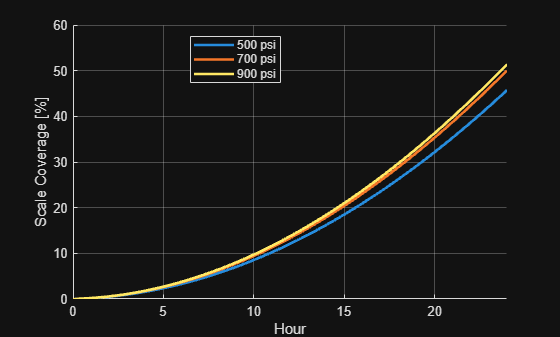

plot_coverage(cases)

## Scaling with Polarization (Exponential Modifier)

Polarization doesn't just show up in desalination dynamic, it also shows up (but in the oposite way) in scaling dynamics. Scaling results in the fluid near the surface to lose salt, lowering the concentration locally an requireing mass transport to replace the salt near the membrane. We can use the same exponential equation to model this behavior as well, but we need to find an effective flux of wate $J_{eff}$. Before this was just the solvent flux but now it needs to represent an effective solvent flux given the mass transport of salt out of the water. To explain this we first need to back up to our deffinition of concentration. At a point the concentration c is:


$$$c = \frac{M_s}{V}$
$$


Where $M_s$ is the mass of salt and $V$ represents a small section of volume (where salt is actually being pulled from, this will cancel out so don't worry too much).

There are two ways of changing the concentration, either change the mass of salt or the volume of solvent the salt is sitting in, we can see this after taking a derivative.


$$$$\frac{dc}{dt} = \frac{dM_s}{dt}\frac{1}{V} - \frac{M_s}{V^2}\frac{dV}{dt}$$$$


In the desalination case, we assumed the salt mass stayed constant and we just reduced the volume of solvent by the flux through the membrane $J_w$.


$$\frac{dc}{dt} = \frac{M_s}{V^2}J_wA_m$$


This simplifies to:


$$\frac{dc}{dt} = cJ_wA_m/V$$


a nice first order differential equation. That's why we use the exponential earlier. But in the scaling case the assumptions switch. We now have constant solvent volume, but are losing salt mass to the mass of the scale $M_{scale}$.


$$$$\frac{dc}{dt} = -\dot M_{scale}\frac{1}{V}$$$$


what's beneficial for us is we don't really care about the method, just that the concentration is changing, so we can represent the change in concentration due to $\dot M_{scale}$ with an effective flux $J_{eff}$


$$J_{eff} = -\frac{\dot M_{scale}}{cA_m}$$


We can then make these work together by adding the actual flux $J_w$ to this so $J_eff$ becomes


$$J_{eff} = J_w-\frac{\dot M_{scale}}{cA_m}$$


Let's enable the exponential modifier polarization and run again, I'm not actually sure what we will see, we could see more scale because of the polariuzation leaving more salt near the membrane to scale, or we could see less scale and more flux with the scale growth being both limited and reducing the concentration near the membrane.

set_param('SWRO/Membrane','polarization_type','3') % Exponential Modifier
set_params_500psi;
out = sim('SWRO');

['SWRO/Solver Configuration']: Initial conditions solve failed to converge.

Caused by:
    Error using SeaWaterReverseOsmosis (line 222)
    all components and nodal across variables involved
    Cannot solve for one or more variables, including dynamic variable derivatives:
    Time derivative of 'Constant_Volume_Chamber_SS.T_I' (Temperature of liquid volume)
    

polarscale_500 = out.simlog;
set_params_700psi;
out = sim('SWRO');
polarscale_700 = out.simlog;
set_params_900psi;
out = sim('SWRO');
polarscale_900 = out.simlog;
cases = {polarscale_500,polarscale_700,polarscale_900};
results = calc_ro_metrics(cases,1800);
results.Applied_Pressure = [500; 700; 900];
PolarScaleResults = ResultsTable(results);
disp(PolarScaleResults)
PolarScaleConcTable = ConcTable(results);
disp(PolarScaleConcTable)
plot_coverage(cases)

## Backwashing

It would be follish to let your membrane reach this level of scaling as this really harms the performance, in real systems, membranes are periodically cleaned. In this model I will include a backwashing procedure, where periodically the membrane operates in reverse, with permeate coming back through the membrane and out the brine side. This removes the scale off the membrane and we can use our osmotic pressure difference to drive this. For this backwashing procedure, we can set a cycle length and a cleaning time. A longer cycle length means less time spent shutting down, cleaning, and starting back up, but also means the membrane sees more scale coverage. Longer cleaning times mean a cleaner membrane when the process is started back up, but will reduce permeate production. Note that I include a 1-minute start up and shut down procedure automatically, so a 60 minute cycle time with a 4 minute clean time means 54 minutes at target pressure.

cycletime = 60; % Minutes
cleantime = 4;  % Minutes


## Helper Functions

function set_params_500psi()
    set_param('SWRO/PS Constant','constant','500')
    set_param('SWRO/PS Constant','constant_unit','psi')
    set_param('SWRO/PS Ramp','slope','500/60')
    set_param('SWRO/PS Ramp','slope_unit','psi/s')
    set_param('SWRO/Resistance','R','1.8579e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end

function set_params_700psi()
    set_param('SWRO/PS Constant','constant','700')
    set_param('SWRO/PS Constant','constant_unit','psi')
    set_param('SWRO/PS Ramp','slope','700/60')
    set_param('SWRO/PS Ramp','slope_unit','psi/s')
    set_param('SWRO/Resistance','R','1.6025e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end

function set_params_900psi()
    set_param('SWRO/PS Constant','constant','900')
    set_param('SWRO/PS Constant','constant_unit','psi')
    set_param('SWRO/PS Ramp','slope','900/60')
    set_param('SWRO/PS Ramp','slope_unit','psi/s')
    set_param('SWRO/Resistance','R','1.3242e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end

function set_params_500psi_backwash(cycletime,cleantime)
    set_param('SWRO/PS Gain','gain','500')
    set_param('SWRO/PS Repeating Sequence','slope',sprintf('[60,%g,60,%g]', cycletime*60 - 60*2 - 60*cleantime, 60*cleantime)')
    set_param('SWRO/Resistance','R','1.8579e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end

function set_params_700psi_backwash(cycletime,cleantime)
    set_param('SWRO/PS Gain','gain','700')
    set_param('SWRO/PS Repeating Sequence','slope',sprintf('[60,%g,60,%g]', cycletime*60 - 60*2 - 60*cleantime, 60*cleantime)')
    set_param('SWRO/Resistance','R','1.6025e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end

function set_params_900psi_backwash(cycletime,cleantime)
    set_param('SWRO/PS Gain','gain','900')
    set_param('SWRO/PS Repeating Sequence','slope',sprintf('[60,%g,60,%g]', cycletime*60 - 60*2 - 60*cleantime, 60*cleantime)')
    set_param('SWRO/Resistance','R','1.3242e+10')
    set_param('SWRO/Resistance','R_unit','Pa*s/m^3')
end


function time_avg = time_avg_after_t0(time,series,t0)
    idx = time>=t0;
    t = time(idx);
    y = series(idx);
    time_avg = trapz(t,y) / (t(end) - t(1));
end

function results = calc_ro_metrics(cases,t0)

nCases = numel(cases);

results.Feed_Flow      = zeros(nCases,1);
results.Flux           = zeros(nCases,1);
results.Recovery       = zeros(nCases,1);
results.Salt_Rejection = zeros(nCases,1);
results.Perm_Conc      = zeros(nCases,1);

t = cell(nCases,1);

for i = 1:nCases
    c = cases{i};

    t{i} = c.Feed.mdot_A.series.time;

    results.Feed_Flow(i) = time_avg_after_t0( ...
        t{i}, ...
        -c.Feed.mdot_A.series.values('kg/min') ./ c.Feed.rho_I.series.values('kg/l'), ...
        t0);

    results.Flux(i) = time_avg_after_t0( ...
        t{i}, ...
        c.Permeate.mdot_A.series.values('kg/hr') ./ c.Feed.rho_I.series.values('kg/l') ./ 7.4, ...
        t0);

    results.Recovery(i) = time_avg_after_t0( ...
        t{i}, ...
        -c.Permeate.mdot_A.series.values('kg/hr') ./ c.Feed.mdot_A.series.values('kg/hr'), ...
        t0);

    results.Salt_Rejection(i) = time_avg_after_t0( ...
        t{i}, ...
        -(c.Brine.mdot_A_x.series.values('kg/hr')+c.Brine.mdot_A_y.series.values('kg/hr')) ./...
        (c.Feed.mdot_A_x.series.values('kg/hr')+c.Feed.mdot_A_y.series.values('kg/hr')), ...
        t0);

    results.Perm_Conc(i) = time_avg_after_t0( ...
        t{i}, ...
        c.Membrane.P.x.series.values('mg/l')+c.Membrane.P.y.series.values('mg/l'), ...
        t0);

    results.Perm_Conc_x(i) = time_avg_after_t0( ...
        t{i}, ...
        c.Membrane.P.x.series.values('mg/l'), ...
        t0);

    results.Perm_Conc_y(i) = time_avg_after_t0( ...
        t{i}, ...
        c.Membrane.P.y.series.values('mg/l'), ...
        t0);
end

results.NDP = zeros(10,nCases);

for ii = 1:10
    for jj = 1:nCases
        results.NDP(ii,jj) = time_avg_after_t0( ...
            t{jj}, ...
            cases{jj}.Membrane.unit(ii).membrane_eqs.NDP.series.values('psi'), ...
            t0);
    end
end

results.Mean_NDP = mean(results.NDP,1).';

end

function ResultsTable = ResultsTable(results)
    ResultsTable = table( ...
        results.Applied_Pressure, ...
        round(results.Feed_Flow(:),1), ...
        round(results.Flux(:),1), ...
        round(results.Recovery(:)*100,1), ...
        round(results.Salt_Rejection(:)*100,1), ...
        round(results.Perm_Conc(:),0), ...
        round(results.Mean_NDP,1), ...
        'VariableNames', { ...
            'Applied Pressure [psi]', ...
            'Feed Flow [L/min]', ...
            'Flux [LMH]', ...
            'Recovery [%]', ...
            'Salt Rejection [%]', ...
            'Permeate Concentration [mg/L]', ...
            'NDP [psi]' ...
        });
end

function ConcTable = ConcTable(results)
    ConcTable = table( ...
        results.Applied_Pressure, ...
        round(results.Perm_Conc(:),0), ...
        round(results.Perm_Conc_x(:),0), ...
        round(results.Perm_Conc_y(:),0), ...
        'VariableNames', { ...
            'Applied Pressure [psi]', ...
            'Permeate Concentration (Total) [mg/L]', ...
            'Permeate Concentration (Solute x) [mg/L]', ...
            'Permeate Concentration (Solute y) [mg/L]' ...
            });
end

function plot_coverage(cases)

figure
hold on

caseNames = ["500 psi","700 psi","900 psi"];

for jj = 1:numel(cases)

    % Time vector for this case
    t = cases{jj}.Membrane.unit(1).membrane_eqs.a_loss.series.time()/3600;

    % Collect coverage from all units
    coverage = [];

    for ii = 1:10
        coverage(:,ii) = ...
            cases{jj}.Membrane.unit(ii).membrane_eqs.a_loss.series.values('1');
    end

    % Mean across units
    plot(t, mean(coverage,2)*100, 'LineWidth', 2)

end

xlabel('Hour')
xlim([0,24])
ylabel('Scale Coverage [%]')

legend(caseNames,'Location','best')
grid on

end

function ResetParams() % NaCl and CaCO3, with no CaCO3 concentration
set_param('SWRO','StopTime','3600*2')        % Full Day
set_param('SWRO/Feed','reservoir_concentration','37.8');
set_param('SWRO/Feed','reservoir_concentration_y','0');
set_param('SWRO/Feed','reservoir_concentration_unit','g/l');
set_param('SWRO/Feed','reservoir_concentration_y_unit','g/l');
set_param('SWRO/Solution Settings (SS)','D','1.32e-3')
set_param('SWRO/Solution Settings (SS)','D_unit','mm^2/s')
set_param('SWRO/Solution Settings (SS)','D_y','0.875e-3')
set_param('SWRO/Solution Settings (SS)','D_y_unit','mm^2/s')
set_param('SWRO/Solution Settings (SS)','rho_species','2.17')
set_param('SWRO/Solution Settings (SS)','rho_species_unit','g/cm^3')
set_param('SWRO/Solution Settings (SS)','rho_species_y','2.711')
set_param('SWRO/Solution Settings (SS)','rho_species_y_unit','g/cm^3')
set_param('SWRO/Solution Settings (SS)','M','58.44')
set_param('SWRO/Solution Settings (SS)','M_unit','g/mol')
set_param('SWRO/Solution Settings (SS)','M_y','100.09')
set_param('SWRO/Solution Settings (SS)','M_y_unit','g/mol')
set_param('SWRO/Solution Settings (SS)','i','2')
set_param('SWRO/Solution Settings (SS)','i_y','2')
set_param('SWRO/Membrane','scaling_y','false')
end